# Lab 2

Ross Smyth

clear, clc, close all
addpath ADSP_ToolBox\

## Project 1

Find the total response, ZIR, and ZSR of the following difference equation:


$$y\left\lbrack n\right\rbrack -0\ldotp 49y\left\lbrack n-2\right\rbrack =30{\left(0\ldotp 8\right)}^n u\left\lbrack n\right\rbrack$$


With the initial conditions of:


$$\begin{array}{l}
y\left\lbrack -1\right\rbrack =15\\
y\left\lbrack -2\right\rbrack =10
\end{array}$$


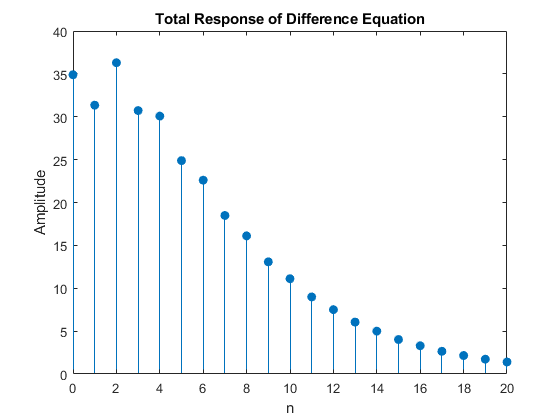

LHS = [1, 0, -0.49];
RHS = [1, 0,  0];
x   = [30, 0.8, 0, 0, 0, 0];
ic  = [15, 10];

% Total Response
[y_tot, ~, ~] = sysresp1('z', RHS, LHS, x, ic);

n = 0:20;
y_tot = eval(y_tot);

figure()
stem(n, y_tot, 'filled')
title('Total Response of Difference Equation')
xlabel('n')
ylabel('Amplitude')

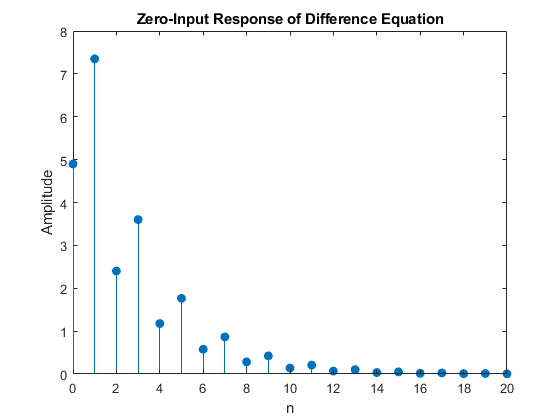

% Zero-input response
x = 30 * (0.8).^n .* ustep(n);
[~, ~, y_zir] = dtsim(RHS, LHS, x, ic);

figure()
stem(n, y_zir, 'filled')
title('Zero-Input Response of Difference Equation')
xlabel('n')
ylabel('Amplitude')

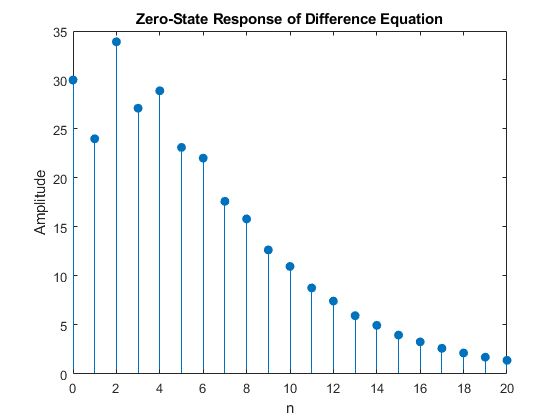

% Zero-state response aka IC = 0
y_zsr = filter(RHS, LHS, x);

figure()
stem(n, y_zsr, 'filled')
title('Zero-State Response of Difference Equation')
xlabel('n')
ylabel('Amplitude')

Looking at the above plots, the response found by recursion by either the `filter` or `dtsim` function looks similar to the total response, which is what would be expected as the equation for finding the total response is the following:


$$y_{\mathrm{tot}} \left\lbrack n\right\rbrack =y_{\mathrm{ZSR}} \left\lbrack n\right\rbrack +y_{\mathrm{ZIR}} \left\lbrack n\right\rbrack$$


RSS = sum(((y_zsr + y_zir) - y_tot).^2)

RSS = 1.0467e-27

To measure the deviation the residual sum of squares is calculated above. With the recursion data being the observed data and the closed-form calculated data being the "truth" data. This shows that the deviation is extremly small, and most likely can be attributed to floating-point math error.

## Project 2

clc, clear, close all

Find the impulse response of the following FIR filter:


$$y\left\lbrack n\right\rbrack =0\ldotp 5\left(x\left\lbrack n\right\rbrack +x\left\lbrack n-1\right\rbrack \right)$$


LHS     = [1 0];
RHS     = [0.5, 0.5];
imp_res = sysresp1('z', RHS, LHS);

Find the response to the input:


$$x\left\lbrack n\right\rbrack =\left\lbrace 2,4,6,8,10,12,14,16\right\rbrace$$


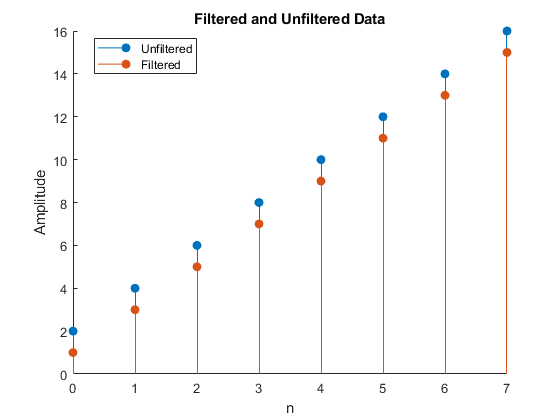

x = 2:2:16;
n = 0:length(x) - 1;
y = filter(RHS, LHS, x);

figure()
hold on
stem(n, x, 'filled')
stem(n, y, 'filled')
title('Filtered and Unfiltered Data')
xlabel('n')
ylabel('Amplitude')
legend({'Unfiltered', 'Filtered'}, 'Location', 'best')
hold off

This is called an "averaging filter" because the response is the average of the data. Specifically the data point in question and N data points behind it. For example looking at $n=3$:


$$\mathrm{Average}=\frac{8+6}{2}=7$$


y(4) % Index 4 as MATLAB is 1 indexed...messed me up.

ans = 7

For a 4-point averaging filter the difference equation would be the following:


$$y\left\lbrack n\right\rbrack =0\ldotp 25\left(x\left\lbrack n\right\rbrack +x\left\lbrack n-1\right\rbrack +x\left\lbrack n-2\right\rbrack +x\left\lbrack n-3\right\rbrack \right)$$


And then for an N-point filter the equation would be:


$$y\left\lbrack n\right\rbrack =\frac{1}{N}\left(x\left\lbrack n\right\rbrack +x\left\lbrack n-1\right\rbrack +x\left\lbrack n-2\right\rbrack \;\ldotp \ldotp \ldotp +\;x\left\lbrack n-N+1\right\rbrack \right)$$


Find the response of the filter:


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -x\left\lbrack n-1\right\rbrack$$


With the input

$x\left\lbrack n\right\rbrack =$`ones(1, 20)`

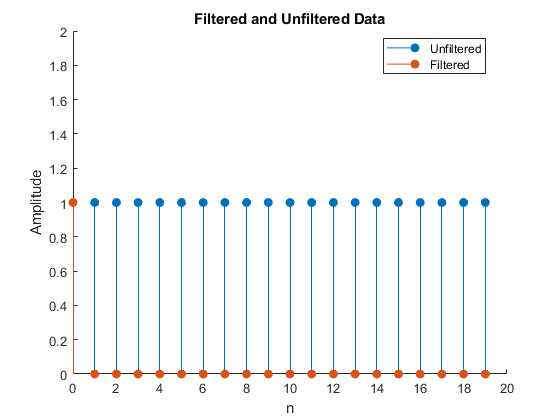

LHS   = [1, 0];
RHS   = [1, -1];
x = ones(1, 20);
y = filter(RHS, LHS, x);

n = 0:length(x) - 1;

figure()
hold on
stem(n, x, 'filled');
stem(n, y, 'filled');
ylim([0 2])
title('Filtered and Unfiltered Data')
xlabel('n')
ylabel('Amplitude')
legend({'Unfiltered', 'Filtered'}, 'Location', 'best')
hold off

Find the response to the input:


$$x\left\lbrack n\right\rbrack =\mathrm{sin}\left(0\ldotp 2n\pi \right)$$


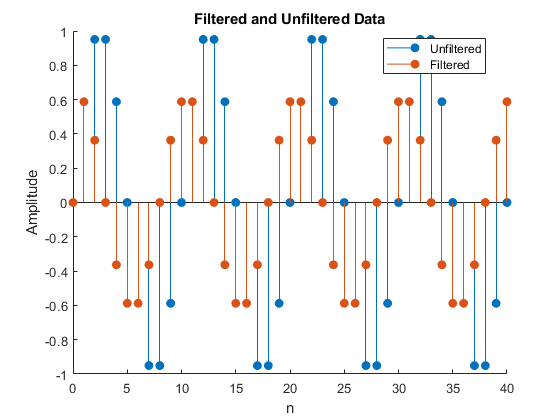

n = 0:40;
x = sin(0.2 * n * pi);
y = filter(RHS, LHS, x);

figure()
hold on
stem(n, x, 'filled');
stem(n, y, 'filled');
title('Filtered and Unfiltered Data')
xlabel('n')
ylabel('Amplitude')
legend({'Unfiltered', 'Filtered'}, 'Location', 'best')
hold off

By looking at the plot directly above, and the previous response generated with an input of ones, it can be seen that this filter does accentuate where large changes occur. For the previous input, the only change is that there was no input and then was. So the change that was accentuated was the single 1 value at the transition. For the above input it is clear that where the change between each value is large, the output is larger. Because of these it makes sense that this filter is called a differentiator, as that is what it seems to do.

Using a 20-point averaging filter confirm that this is smoothing filter.

Using 200 samples of a 1 Hz sine wave sampled at 50 Hz, add noise and then filter it with the averaging filter.

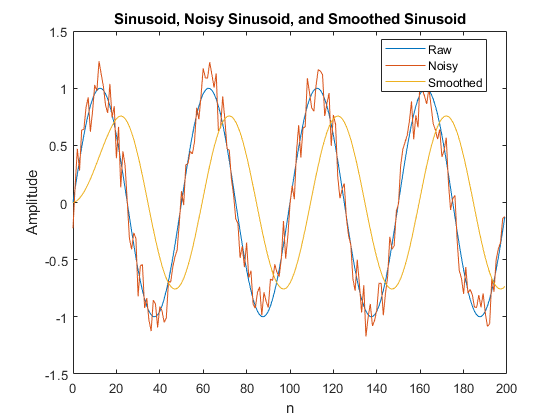

LHS = 1;
RHS = 1 / 20 * ones(1, 20);

n  = 0:199;
x  = sin(2 * pi * n * 1/50);
xe = x + 0.5 * randist(x, 'uni', 0);

y = filter(RHS, LHS, x);

figure()
plot(n, x, n, xe, n, y)
title('Sinusoid, Noisy Sinusoid, and Smoothed Sinusoid')
xlabel('n')
ylabel('Amplitude')
legend({'Raw', 'Noisy', 'Smoothed'}, 'Location', 'best')

% Phase
[r, lags] = xcorr(y, x);
[~, i]    = max(r);
samp_lag  = lags(i)

samp_lag = 9

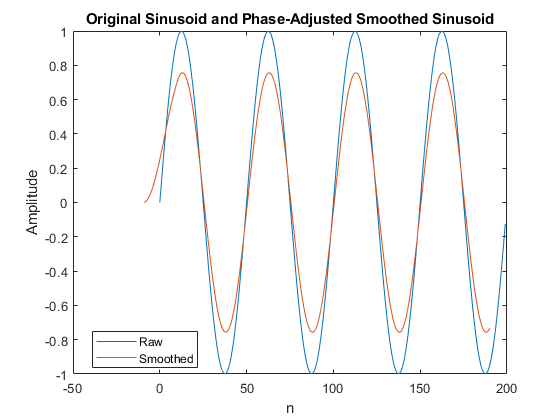


figure()
plot(n, x, n - samp_lag, y)
title('Original Sinusoid and Phase-Adjusted Smoothed Sinusoid')
xlabel('n')
ylabel('Amplitude')
legend({'Raw', 'Smoothed'}, 'Location', 'best')

Using a technique that I have used previously I used the cross-correlation function to determine that sample lag of the two signals. In this case the sample lag is 9 samples.

% Gain
gain = max(x) / max(y)

gain = 1.3178

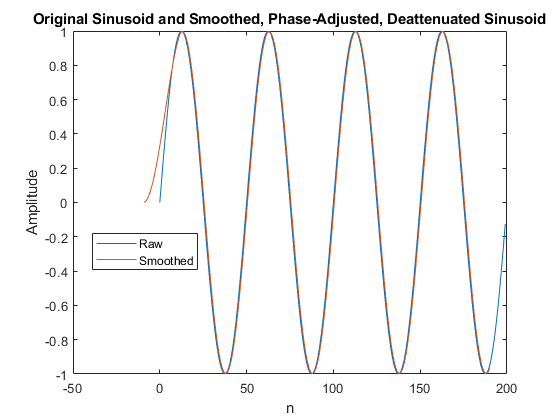

RHS = RHS * gain;

y = filter(RHS, LHS, x);

figure()
plot(n, x, n - samp_lag, y)
title('Original Sinusoid and Smoothed, Phase-Adjusted, Deattenuated Sinusoid')
xlabel('n')
ylabel('Amplitude')
legend({'Raw', 'Smoothed'}, 'Location', 'best')

1/20 * gain

ans = 0.0659

Since it is a linear signal, just finding the ratio between the peaks of the signals will give the gain needed to get the correct multiplier. In this case the ratio is 1.32, leading to a coefficient on the RHS of the equation of `0.0659`.

The signal has attenuation and a phase-shift because the averaging filter is looking in the past and at many values in the past. The first samples will be averaged with mostly zeros, but eventually the filter will have values in it. This filling of the filter inputs as the filter moves along the signal causes the lag in the filter response. The attentuation is due to the many samples being averaged. At the peak of the signal the sample in question would be at the peak, but the 20 samples being averaged would be behind, and therefore lesser in magnitude pulling the output sample value down.